clc
clear all

load("result/theta_throughput.mat")
load("result/gamma_throughput.mat")

theta_throughput = theta_throughput_for_n;
gamma_throughput = gamma_throughput_for_n;

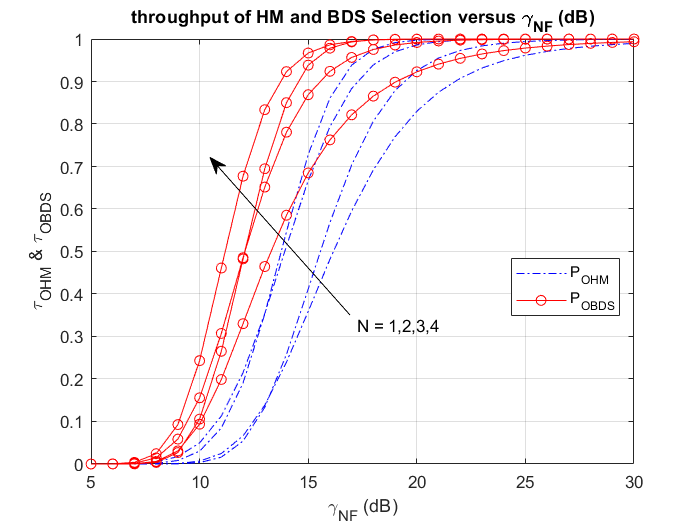

gamma_NF_db = [5:30];
gamma_NF = 10.^(gamma_NF_db/10);

figure
plot(gamma_NF_db, gamma_throughput, '-.b');
hold on
plot(gamma_NF_db, theta_throughput, '-or');

legend({'P_{OHM}', '', '', '', 'P_{OBDS}'}, 'Location', 'best')


xlabel('\gamma_{NF} (dB)'); ylabel('\tau_{OHM} & \tau_{OBDS}');
title('throughput of HM and BDS Selection versus \gamma_{NF} (dB)')
grid on, hold on
% ylim([1e-4 1])
% xlim([1 15])
xticks(5:5:30)

annotation('textarrow', [0.5,0.3], [0.4,0.7], 'String', 'N = 1,2,3,4', 'LineWidth', 0.1);